% Modelling ML

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

% ********** 1) Baseline Models **********

% 1a) Baseline Decision Tree
disp('Baseline Decision Tree')
% Train
dt_base = fitctree(X_train, y_train);
% Evaluate baseline tree
y_pred = predict(dt_base, X_test);
[accuracy, precision, recall, specificity, f1] = binary_eval_metrics(y_test, y_pred) %#ok<ASGLU> 

accuracy = 0.9206

precision = 0.1429

recall = 0.0943

specificity = 0.9677

f1 = 0.1136

% 1b) Baseline Random Forest
disp('Baseline Random Forest')
% Train
rf_base = fitcensemble(X_train, y_train, 'Method', 'Bag');
% Evaluate
y_pred = predict(rf_base, X_test);
[accuracy, precision, recall, specificity, f1] = binary_eval_metrics(y_test, y_pred) %#ok<ASGLU> 

accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

f1 = 0

% 1c) Baseline KNN
disp('Baseline KNN')
% Train
knn_base = fitcknn(X_train, y_train, 'NumNeighbors', 2 ,'Standardize',1);
% Evaluate baseline knn
y_pred = predict(knn_base, X_test);
[accuracy, precision, recall, specificity, f1] = binary_eval_metrics(y_test, y_pred)

accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

f1 = 0

% ********** 2) Tuned Models **********

nrow = 3926

ncol = 17

cv_part = K-fold cross validation partition
   NumObservations: 3926
       NumTestSets: 10
         TrainSize: 3534  3533  3533  3533  3533  3533  3533  3534  3534  3534
          TestSize: 392  393  393  393  393  393  393  392  392  392

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |      MinLeaf |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.89535 |    0.011336 |     0.89535 |     0.89535 |           12 |            4 |
|    2 | Accept |           1 |    0.012768 |     0.89535 |     0.90078 |           11 |           23 |
|    3 | Accept |           1 |    0.012047 |     0.89535 |     0.89536 |           24 |           25 |
|    4 | Accept |     0.92683 |    0.012259 |     0.89535 |     0.91477 |           23 |            4 |
|    5 | Accept |           1 |    0.011483 |     0.89535 |     0.90265 |            2 |            2 |
|    6 | Accept |     0.89535 |     0.01171 |     0.89535 |     

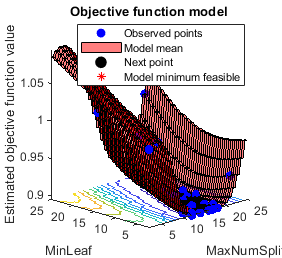

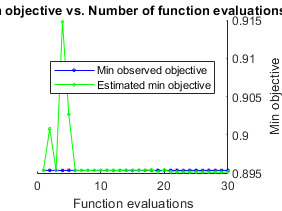


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 17.5038 seconds
Total objective function evaluation time: 0.36962

Best observed feasible point:
    MaxNumSplit    MinLeaf
    ___________    _______

        12            4   

Observed objective function value = 0.89535
Estimated objective function value = 0.89543
Function evaluation time = 0.011336

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeaf
    ___________    _______

        20           12   

Estimated objective function value = 0.89513
Estimated function evaluation time = 0.012172



% 2a) i) Optimized Tree
% Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[2,25],'Type','integer');
MinLeaf = optimizableVariable('MinLeaf',[2, 25],'Type','integer');
paramsTree = [MaxNumSplit; MinLeaf];
% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)f1_loss_dt(params,X_train,y_train),paramsTree,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

% Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train,y_train,'MaxNumSplits',z.MaxNumSplit,'MinLeafSize',z.MinLeaf);

% Evaluate
y_pred = predict(dt_best, X_test);
[accuracy, precision, recall, specificity, f1] = binary_eval_metrics(y_test, y_pred) %#ok<ASGLU>

% --> model overfits

% 2a) ii) Optimized Tree with cross validation
% Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train)

nrow = 3926

ncol = 17

cv_part = cvpartition(nrow,'KFold', 10)

cv_part = K-fold cross validation partition
   NumObservations: 3926
       NumTestSets: 10
         TrainSize: 3534  3533  3533  3533  3533  3533  3533  3534  3534  3534
          TestSize: 392  393  393  393  393  393  393  392  392  392

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MaxNumSplit |      MinLeaf |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.98742 |     0.77664 |     0.98742 |     0.98742 |            9 |           17 |
|    2 | Accept |           1 |     0.13856 |     0.98742 |     0.98846 |            3 |            8 |
|    3 | Accept |           1 |     0.16718 |     0.98742 |     0.98883 |           15 |           23 |
|    4 | Best   |     0.97605 |     0.10597 |     0.97605 |     0.97864 |           14 |            2 |


|    5 | Best   |      0.9759 |      0.1057 |      0.9759 |     0.97598 |           14 |            3 |


|    6 | Accept |           1 |    0.097149 |      0.9759 |     0.97598 |            8 |           18 |
|    7 | Best   |     0.95294 |     0.13846 |     0.95294 |     0.95294 |           13 |            8 |
|    8 | Accept |           1 |     0.11019 |     0.95294 |     0.95324 |           12 |           25 |
|    9 | Accept |     0.97576 |     0.10738 |     0.95294 |     0.96639 |           12 |           10 |
|   10 | Accept |     0.95294 |     0.10767 |     0.95294 |     0.95294 |           14 |            8 |
|   11 | Accept |     0.96386 |    0.099207 |     0.95294 |     0.95294 |           14 |            7 |
|   12 | Accept |     0.95402 |     0.11399 |     0.95294 |     0.95293 |           15 |            9 |
|   13 | Accept |      0.9558 |     0.12474 |     0.95294 |     0.95293 |           18 |            9 |
|   14 | Best   |     0.94595 |     0.10755 |     0.94595 |     0.95219 |           22 |            8 |
|   15 | Accept |      0.9558 |     0.16289 |     0.94595 |     

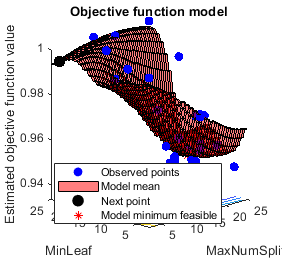

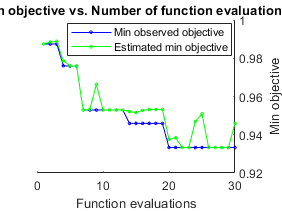


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 24.5603 seconds
Total objective function evaluation time: 4.1804

Best observed feasible point:
    MaxNumSplit    MinLeaf
    ___________    _______

        25           17   

Observed objective function value = 0.93333
Estimated objective function value = 0.95023
Function evaluation time = 0.12036

Best estimated feasible point (according to models):
    MaxNumSplit    MinLeaf
    ___________    _______

        25           15   

Estimated objective function value = 0.94598
Estimated function evaluation time = 0.12379




% Define vars and range
MaxNumSplit = optimizableVariable('MaxNumSplit',[2,25],'Type','integer');
MinLeaf = optimizableVariable('MinLeaf',[2, 25],'Type','integer');
ParamsDT= [MaxNumSplit; MinLeaf];

% Optimize the variables by bayesian optimizer
results = bayesopt(@(params)f1_loss_dt_cv(params,X_train,y_train, cv_part), ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

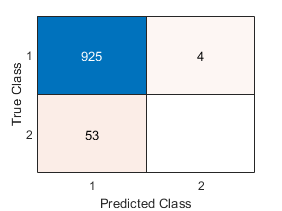

accuracy = 0.9420

precision = 0

recall = 0

specificity = 0.9957

f1 = 0

function f1 = f1_loss_dt_cv(params, X_train, y_train, cv_part)
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeaf);
        
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, f1] = binary_eval_metrics(y_train, y_pred);
        f1=1-f1;  % Convert to f1-"loss"
end

function f1 = f1_loss_dt(params, X_train, y_train)
        model=fitctree(X_train,y_train,'MaxNumSplits',params.MaxNumSplit,'MinLeafSize',params.MinLeaf);
        
        % Calculate F1 score
        y_pred = predict(model,X_train);
        [~, ~, ~, ~, f1] = binary_eval_metrics(y_train, y_pred);
        f1=1-f1;  % Convert to f1-"loss"
end

function [acc, prec, rec, spec, f1] = binary_eval_metrics(y_test, y_pred)
    % Evaluation metrics for binary classification
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);
    %confusionchart(cmat);

    % Statistics of interest for confusion matrix
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    f1 = tp / (tp + 0.5*(fp + fn));
end